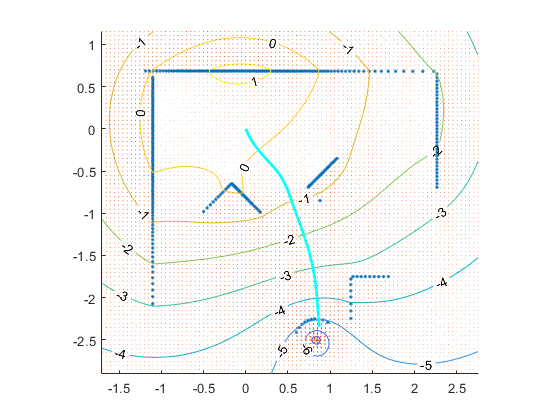

load('data/gauntlet_data.mat')
pos_matrix = generate_map;

% Dataset row format
% [timestamp, positionLeft, positionRight, AccelX, AccelY, AccelZ];
dtime = diff(dataset(:, 1));
mV_L = diff(dataset(:, 2)) ./ dtime;
mV_R = diff(dataset(:, 3)) ./ dtime;
time = dataset(2:end, 1) - dataset(2, 1);

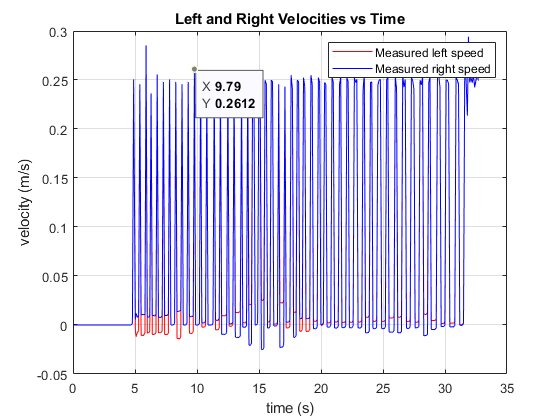

clf
plot(time, mV_L, 'r-', time, mV_R, 'b-')
title('Left and Right Velocities vs Time')
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('Measured left speed', 'Measured right speed')
grid on

d_num = 0.235;
mV_T = (mV_L + mV_R) / 2;
mw = (mV_R - mV_L) / d_num;

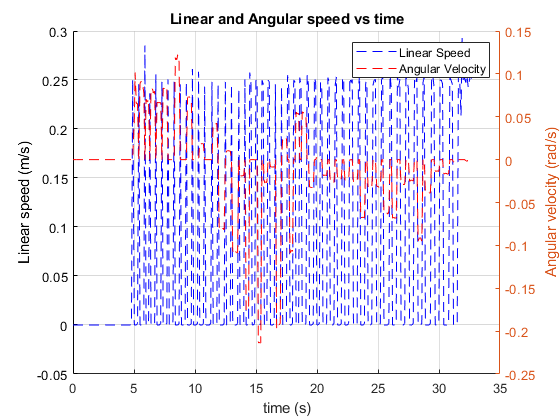

clf
hold on
plot(time, mV_T, 'b--');
xlabel('time (s)')
ylabel('Linear speed (m/s)')

yyaxis right
plot(time, mw, 'r--')
xlabel('time (s)')
ylabel('Angular velocity (rad/s)')

title('Linear and Angular speed vs time')
legend('Linear Speed', 'Angular Velocity')
grid on
hold off

m_angle = zeros(size(mw));
angle = atan2(((pos_matrix(2,2)-pos_matrix(1,2))) , ((pos_matrix(2,1)-pos_matrix(1,1))));

m_vel = zeros(size(mV_T, 1), 2);
m_pos = zeros(size(mV_T, 1), 2);
pos = [pos_matrix(1, 1), pos_matrix(1, 2)];

% Solve the integrals to generate position
for n=1:length(dtime)
    angle = angle + mw(n) * dtime(n);
    m_angle(n) = angle;
    
    rot = [
        cos(angle) -sin(angle);
        sin(angle) cos(angle)
    ];
    
    mV = (rot * [mV_T(n); 0])';
    m_vel(n, :) = mV;
    pos = pos + (mV .* dtime(n));
    m_pos(n, :) = pos';
end

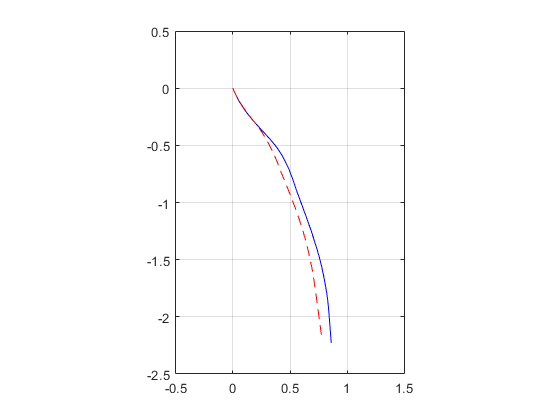

clf
plot(pos_matrix(:, 1), pos_matrix(:, 2), 'b', m_pos(:, 1), m_pos(:, 2), 'r--')
axis equal
xlim([-0.5 1.5])
ylim([-2.5 0.5])
grid on